Open the Data File

clear all
path = 'Z:\My Documents\PMUCal\Output\'

path = 'Z:\My Documents\PMUCal\Output\'

name = 'SavedFit.mat'

name = 'SavedFit.mat'

name = strcat(path,name);
A = open(name);
P = A.P;
clear A;

Get the samples in the row of interest

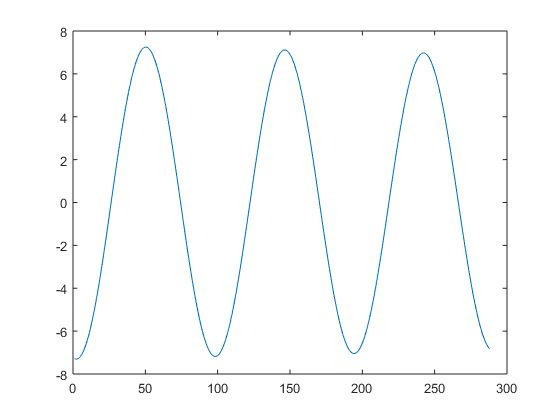

i = 7;
SignalParams = P(i).SignalParams;
DelayCorr = P(i).DelayCorr;
MagCorr = P(i).MagCorr;
F0 = P(i).F0;
AnalysisCycles = P(i).AnalysisCycles;
SampleRate = P(i).SampleRate;
Samples = P(i).Samples;
plot(Samples(1,:))

Run the Steady State Fitter

    [Synx,Freq,ROCOF,iterations] = ModulationFit ( ...
        SignalParams, ...
        DelayCorr, ...
        MagCorr, ...
        F0, ...
        AnalysisCycles, ...
        SampleRate, ...
        Samples ...
        )

Synx = 	1.0e+02 *

   1.0492 - 0.1298i   0.1280 + 1.0461i  -0.1193 - 1.1058i  -0.2729 + 0.0381i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i


Freq = 50.0011

ROCOF = -9.9638e-04

iterations =      1
     4
     4
     1
     2
    21
